# **FORÅR 2018 EKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 SANDSYNLIGHED**

Et system er udviklet til at registrere om RFID tags er defekte. En undersøgelse viser, at givet et RFID tag ikke er defekt, er sandsynligheden for, at systemet registrerer, at det ikke er defekt lig med 0.4. Givet et RFID tag er defekt, er sandsynligheden for, at systemet registreret, at det er defekt lig med 0.999. Det vides, at 1 ud af 100 RFID tags er defekte.

A : RFID DEFEKT 

B : REGISTRER DEFEKT


$$P\left(A\right)=\frac{1}{100}$$



$$P\left(\overline{B} |\overline{A} \right)=0\ldotp 4$$



$$P\left(B|A\right)=0\ldotp 999$$


A = 1/100;
NotBGivenNotA = 0.4;
BGivenA = 0.999;

## 1.1 IKKE DEFEKT

For at bestemme sandsynligheden for at RFID tag ikke er defekt anvendes, at


$$P\left(A\right)=1-P\left(\overline{A} \right)$$


NotA = 1 - A

NotA = 0.9900

Sandsynligheden er dermed bestemt til at være 0.99.

## 1.2 TOTALE SANDSYNLIGHED

For at bestemme den totale sandsynligheden for at systemet registerer et RFID tag som er defekt anvendes, at


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$



$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


BGivenNotA = 1 - NotBGivenNotA;

B = BGivenA * A + BGivenNotA * NotA

B = 0.6040

Sandsynligheden er dermed bestemt til at være 0.6040 altså 60.40%.

## 1.3 BETINGET SANDSYNLIGHED

For at bestemme hvad sandsynligheden for at et RFID tag er defekt givet at det er registreret som defekt anvendes, at


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


AGivenB = (BGivenA * A) / B

AGivenB = 0.0165

Sandsynligheden er dermed bestemt til at være 0.0165 altså 1.65%.

## 1.4 BETINGER SANDSYNLIGHED 2

For at bestemme hvad sandsynligheden for at et RFID tag ikke er defekt givet at det er registreret som defekt anvendes, at


$$P\left(\overline{A} |B\right)=\frac{P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)}{P\left(B\right)}$$


%NoAGivenB = 1 - AGivenB
NotAGivenB = (BGivenNotA * NotA) / B

NotAGivenB = 0.9835

Sandsynligen er dermed bestemt til at være 0.9835 altså 98.35%.

# **2 STOKASTISKE VARIABLE**

En tæthedsfunktion for en stokastisk variabel er defineret til at være 

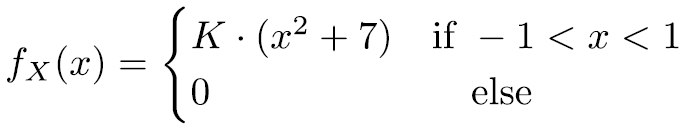

## 2.1 GYLDIG TÆTHEDSFUNKTION

For en gyldig tæthedsfunktion gælder, at


$$\int_{-\infty }^{\infty } f_X \left(x\right)\mathrm{dx}=1$$


Hvor $k$ kan isoleres og beregnes som følgende i matlab.

syms fx(x) k
fx(x) = piecewise(-1<x<1, k*(x^2 + 7), 0);
k = solve(int(fx(x), -inf, inf) == 1, k)

$$k = \frac{3}{44}$$

Dermed er $k$ bestemt til at være lig med $\frac{3}{44}$ for at $f_X \left(x\right)$er en gyldig tæthedsfunktion.

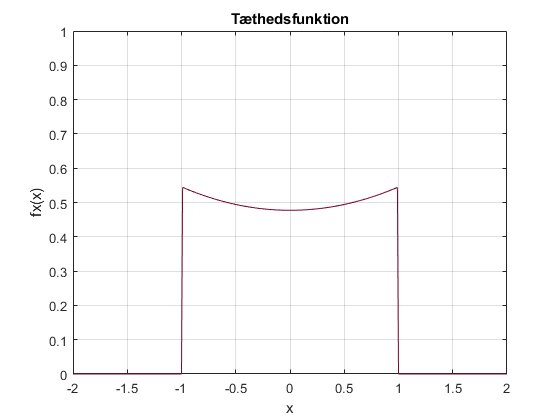

syms fx(x) 
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);
x = -2:0.01:2;

figure(1)
plot(x, fx(x), 'Color', Color.DeepCleret);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
axis([-2, 2, 0, 1]);

## 2.2 MIDDELVÆRDI

For at bestemme middelværiden anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$



$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x*((3/44)*(x^2 + 7)), 0);

MeanValue = int(xfx(x), -inf, inf)

$$MeanValue = 0$$

Dermed middelværiden bestemt til at være 0.

## 2.3 VARIANS

For at bestemme standard afvigelsen benyttes, at


$$\mathrm{Var}\left(x\right)=\sigma^2 =\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$



$$\sigma =\sqrt{\sigma^2 }$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x^2*((3/44)*(x^2 + 7)), 0);

MeanSquareValue = int(xfx(x), -inf, inf);

Variance = MeanSquareValue - MeanValue^2;
StandardDeviation = sqrt(Variance)

$$StandardDeviation = \frac{\sqrt{19}\,\sqrt{55}}{55}$$

(sqrt(19)*sqrt(55)) / 55

ans = 0.5878

Standard afvigelsen er dermed bestemt til at være 0.5878.

## 2.4 FORDELINGSFUNKTION

For at finde fordelingsfunktionen anvendes, at


$$F_X \left(x\right)=\int_{-\infty }^x f_X \left(x\right)\mathrm{dx}$$


syms fx(x) k
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);

int(fx(x), -inf, x)

$$ans = \left\{ \begin{array}{cl} 1 & \text{ if }1\leq x\\ 0 & \text{ if }x\leq -1\\ \frac{x^{3}}{44}+\frac{21\,x}{44}+\frac{1}{2} & \text{ if }x\in \left(-1,1\right] \end{array}\right.$$

# **3 STOKASTISKE PROCESSER**

En kontinuert stokastisk process er givet ved


$$y\left(t\right)=x\left(t\right)+w$$


hvor $x\left(t\right)\sim N\left(0,t^2 \right)$og $w\sim N\left(3,1\right)$. x og w er uafhængige.

## 3.1 REALISERING

Realiseringen af lavet i matlab.

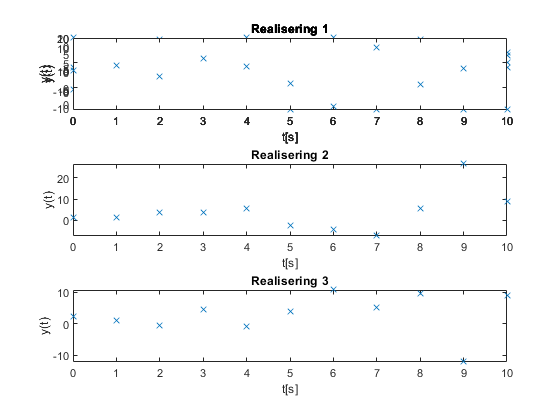

t = 0:1:10;


nmu = 3;
nvariance = 1;

xmu = 0;
xvariance = t.^2;

y = [[],[],[]];

for n = 1:3
    w = sqrt(nvariance) * randn + nmu;
    x = sqrt(xvariance) .* randn(1, 11) + xmu;    
    y(n, :) = x + w;
end

figure(2)
subplot(3,1,1,gca)
plot(t, y(1, :), 'x');
title('Realisering 1');
xlabel('t[s]');
ylabel('y(t)');

subplot(3,1,2)
plot(t, y(2, :), 'x');
title('Realisering 2');
xlabel('t[s]');
ylabel('y(t)');

subplot(3,1,3)
plot(t, y(3, :), 'x');
title('Realisering 3');
xlabel('t[s]');
ylabel('y(t)');
hold off

## 3.2 ENSEMBLE MIDDELVÆRDI

For at bestemme middelværiden anvendes, at


$$E\left\lbrack y\left(t\right)\right\rbrack =E\left\lbrack x\left(t\right)+w\right\rbrack =E\left\lbrack x\left(t\right)\right\rbrack +E\left\lbrack w\right\rbrack$$


EnsembleMean = xmu + nmu

EnsembleMean = 3

Middelværdien for ensemble er dermed bestemt til at være 3.

## 3.3 ENSEMBLE VARIANS

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left\lbrack y\left(t\right)\right\rbrack =\mathrm{Var}\left(x\left(t\right)+w\right)=\mathrm{Var}\left\lbrack x\left(t\right)\right\rbrack +\mathrm{Var}\left\lbrack w\right\rbrack$$


syms t
EnsembleVariance = t^2 + nvariance

$$EnsembleVariance = t^{2}+1$$

Variansen for ensemble er dermed bestemt til at være $t^2 +1$.

## 3.4  TIDSLIG MIDDELVÆRDI

For at bestemme den tidslige middelværdi og varians for en realisation af processen kan følgende anvendes.


$$\hat{\mu_{X_i } } =\left\langle X_i \right\rangle =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x_i \left(t\right)\mathrm{dt}$$



$$\hat{\sigma_{X_i }^2 } ={\left\langle X_i^2 \right\rangle }_T -{\left\langle X_i \right\rangle }_T^2 =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} \left(x_i {\left(t\right)}^2 -{\hat{\mu_{X_i } } }^2 \right)\mathrm{dt}$$


For middelværdien gælder, at


$$\hat{\mu_{Y_1 } } =\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N \left(y_1 \left(n\cdot T\right)\right)=\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N \left(x_1 \left(n\right)+w_1 \right)=0+w_1 =w_1$$


For variansen gælder, at


$${\hat{\sigma_{Y_1 } } }^2 =\lim_{N\to \infty } \frac{1}{N}\sum_{n=0}^N \left(y_1^2 \left(n\cdot T\right)-{\hat{\mu_{Y_1 } } }^2 \right)=\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N {\left(x_1 \left(n\right)+w_1 \right)}^2 -w_1^2 =\infty =\left(t^2 \right)$$


## 3.5 PROCESSEN

Da den tidslige varians er forskellige fra ensemble varians er processen ikke WSS. Da processen ikke er WSS er processen heller ikke ergodisk.

# **4 STATISTIK**

Til kvalitetssikring af en produktion er udviklet et automatisk overvågningssystem, der skal registrere om en komponent er monteret korrekt. Overvågningssystemet skal i 95% af tilfældene registrere komponenterne korrekt, dvs. fejl-monterede komponenter registreres som fejl og korrekt-monterede komponenter registreres som korrekte.

For at undersøge om systemet overholder dette krav laves en række måleserier på et produkt A, hvor der testes om overvågningssystemets succesrate er præcis 95%. Testen består af i alt 15 måleserier. Hver serie består af 100 enheder, hvor antallet af korrekte registreringer (successer) noteres.

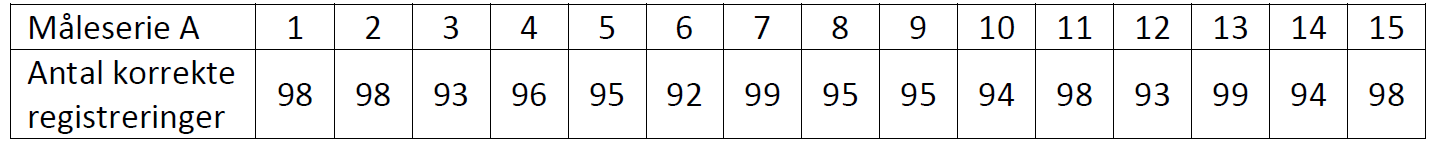

## 4.1 ESTIMERET SUCCESRATE - SANDSYNLIGHED

ProductA = [98, 98, 93, 96, 95, 92, 99, 95, 95, 94, 98, 93, 99, 94, 98];
Length = length(ProductA);

ProductsInSeries = 100;
Measurements = Length * ProductsInSeries;

SuccesRate = sum(ProductA) / Measurements;

Den estimerede succesrate er bestemt til at være 0.9580.

## 4.2 TEST STATISTIK

Da testen er baseret på succes eller fiasko anvendes en binomialfordeling hvor følgende betingelser skal være opfyldt.


$$\mathrm{np}>5\;\mathrm{og}\;n\left(1-p\right)>5$$


hvor 

N = Measurements; P = SuccesRate;

N * P 

ans = 1437

N*(1-P)

ans = 63.0000

Der opstilles en null hypoteser samt en alternativ hypotese som følgende.


$$H_0 :$$
  
$$p=0\ldotp 95$$



$$H_1 :$$
  
$$p\not= 0\ldotp 95$$


## 4.3 P-VÆRDI

For at bestemme p værdien anvendes først, at


$$Z=\frac{X-E\left\lbrack X\right\rbrack }{\sqrt{\mathrm{Var}\left(X\right)}}=\frac{X-\mathrm{np}}{\sqrt{\mathrm{np}\left(1-p\right)}}$$


Z = (sum(ProductA) - Measurements * 0.95) / sqrt(Measurements * 0.95*(1-0.95))

Z = 1.4216

Z er dermed bestemt til at være 1.4216. For at bestemme om NULL hypotesen kan afvises findes p-værdien.

p = 2 * abs(1 - normcdf(abs(Z), 0, 1))

p = 0.1551

Null hypotesen kan altså ikke afvises da p værdien er større end 0.05.

## 4.4 KONFIDENSINTERVAL

For at bestemme konfidensintervallet anvendes, at


$$p_{\pm } =\frac{1}{n+1\ldotp {96}^2 }\left\lbrack x+\frac{1\ldotp {96}^2 }{2}\pm 1\ldotp 96\cdot \sqrt{\frac{x\left(n-x\right)}{n}+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$


x = sum(ProductA);
n = Measurements;

step = (1/(n+1.96^2));

delta.one = x + (1.96^2 / 2);
delta.two = 1.96 * sqrt( ((x*(n-x))/n) + ((1.96^2)/4));

Interval.min = step * (delta.one - delta.two);
Interval.max = step * (delta.one + delta.two);

Interval

Interval = struct with fields:
    min: 0.9466
    max: 0.9670


## 4.5 TEST AF DATASÆT

For at undersøge om de to datasæt er forskellige anvendes en uparret samneligningstest af to populationer med ukendt varians også bekendt som uparret t-test. Testen skal være uparret der der ikke er en relation mellem en enhed fra det ene produkt til en enhed fra det andet produkt. Desuden er det et antal forskellige målinger. De to populationer antages at have ens men ukendt varians.

## 4.6 NULL HYPOTESE - TEST MV.

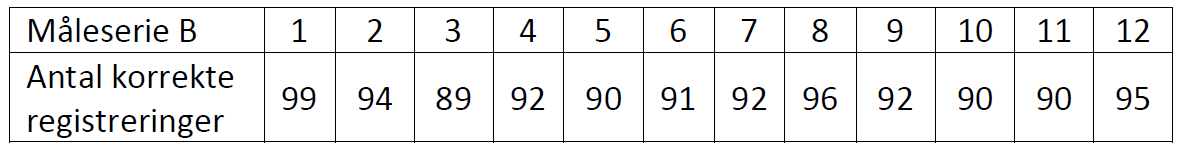

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme. Altså om det gennemsnitslige antal korrekt monitorerede enheder pr. måling er ens for de to produkter.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


Det gennemsnitslige antal korrekte enheder pr. måling estimeres som følgendes.


$$n_A =\frac{N_{\mathrm{Akorrekte}} }{15}$$



$$n_B =\frac{N_{\mathrm{Bkorrekte}} }{12}$$


ProductB = [99, 94, 89, 92, 90, 91, 92, 96, 92, 90, 90, 95];

Na = sum(ProductA) / 15;
Nb = sum(ProductB) / 12;

Den poolede varians bestemmes ud fra de to sample varianser hvilke beregnes som følgende.


$$s^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\mu^ˆ \right)}^2$$



$${s_p }^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


SampleVariance.A =  (1 / (15 - 1)) * sum((ProductA - Na).^2);
SampleVariance.B = (1 / (12 - 1)) * sum((ProductB - Nb).^2);

PooledVariance = (1 / (15 + 12 - 2)) * (((15-1)*SampleVariance.A) + ((12-1)*SampleVariance.B))

PooledVariance = 7.0160

Dernæst anvendes t-værdi som bestemmes ud fra følgende.


$$t=\frac{\overline{x_1 } -\overline{x_2 } -\delta }{s_p \cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}}$$


t = (Na - Nb) / (sqrt(PooledVariance) * sqrt(1/15 + 1/12));

p = 2 * (1 - tcdf(abs(t), 15 + 12 - 2))

p = 0.0036

Da p værdien er under 0.05 kan null hypotesen afvises og overvågningssystemet virker forskelligt på de to typer produkter.